### **Complete the following steps first:**

- **Sort and clean up tracking data (need 4 files from Bonsai: stim, position, avi and avi frame log). Use DLCLabelCuration as a tool for semi-manual curation.**

- **Move MED and Bpod data to this folder **

**To run this live script, load the following files (automatically), after this, everything will just flow. **

**After the run, the script will generate a table containing all useful information regarding press, opto, dlc, approach, etc. It also plots a figure showing approach-to-press and DLC-to-press. **

**Jianing Yu 2022.3.25**

clear;
close all;
% clear workspace first

% 1. load PosData (This is DLCLabelCuration)
PosDataFile = dir('PosData*Updated.mat')

PosDataFile = struct with fields:
       name: 'PosData_Claire_position2022-01-17T14_53_05Updated.mat'
     folder: 'E:\DLSOpt\Data\ANMs\Claire\Sessions\20220117'
       date: '23-Mar-2022 13:46:04'
      bytes: 220850
      isdir: 0
    datenum: 7.3860e+05


load(PosDataFile.name)

% 2. load MED data
MEDFile = dir('*Subject*.txt');
MEDFilePostAnalysis = dir(['B_*.mat']);

%% Extract behavior times from MED
% bout=track_training_progress_advanced('2020-01-23_15h58m_Subject Lucky.txt');

if isempty(MEDFilePostAnalysis)
    track_training_progress_advanced(MEDFile.name);
else
    load(MEDFilePostAnalysis.name)
end;

% 3. load Bpod data
FindBpodFile = dir('*MedOptoRecMix*.mat');

if ~isempty(FindBpodFile)
    BpodFile = FindBpodFile.name;
    load(BpodFile)
else
    disp('No Bpod file or what?')
    return
end;


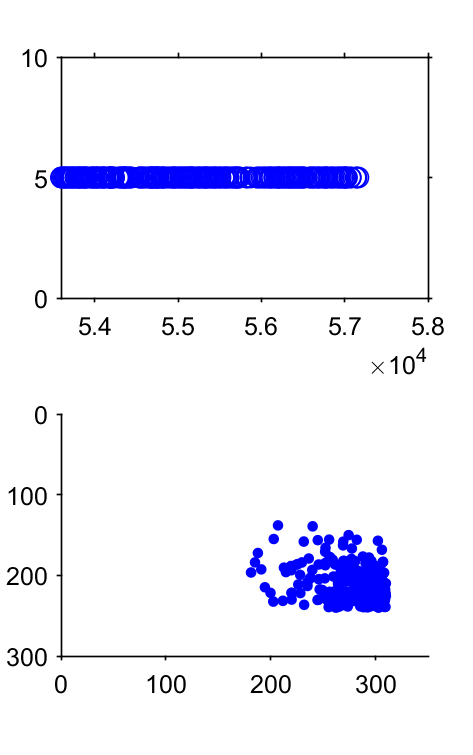

iClust = 1; % use cluster 1 for analysis

indClus = find(PosData.StimClus{iClust});
StimTimesClus = PosData.StimTime(indClus, 1);  % time that s softcode was sent

% only use well-spaced events
Ind_StimTimeClusWellSpaced = [1; find(diff(StimTimesClus)>1)+1];
indClus = indClus(Ind_StimTimeClusWellSpaced);
StimTimesClus = StimTimesClus(Ind_StimTimeClusWellSpaced);

hf1 = figure; clf
set(hf1, 'units', 'centimeters', 'position', [5 5 5 8])
subplot(2, 1, 1);
plot(StimTimesClus, 5, 'bo')
hold on
% plot(StimTimesClus2, 6, 'ro')
set(gca, 'ylim', [0 10])
subplot(2, 1, 2)
set(gca, 'xlim', [0 350], 'ylim', [0 300], 'nextplot', 'add')
scatter(PosData.StimPos(indClus, 1), PosData.StimPos(indClus, 2), 10, 'b', 'filled')
hold on
% plot(PosData.StimPos(indClus2, 1), PosData.StimPos(indClus2, 2), 'ro')
set(gca, 'ydir', 'reverse')


sprintf('number of stim %2.0d', length(StimTimesClus))

ans = 'number of stim 254'

### Assign meaning to each stim point in Cluster 1 

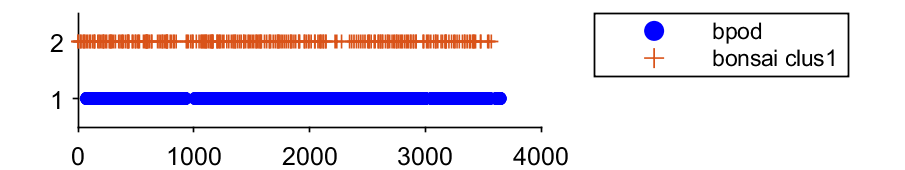

% iVidFile = app.VideofileDropDown.Value;
% PosData = app.UpdatePosDataButton.UserData; %
% vidout = ExtractStimFrames(iVidFile, PosData, 'Updated');
% 
% app.DLCframesvidfileDropDown.Items = {vidout};

% extract softcdoe from Bpod

% extract all softcode times

softcode_times      =       []; % to doc each softcode's time
softcode_trials     =       []; % to label each softcode's trial number

for i =1:length(SessionData.RawEvents.Trial)
    t_thistrial = SessionData.TrialStartTimestamp(i);

    % check if there is a softcode6
    if isfield(SessionData.RawEvents.Trial{i}.Events, 'SoftCode6')
        softcode_times  = [softcode_times SessionData.RawEvents.Trial{i}.Events.SoftCode6 + t_thistrial];
        softcode_trials = [softcode_trials i*ones(1, length(SessionData.RawEvents.Trial{i}.Events.SoftCode6))];
    end;
end;

% softcode_times = softcode_times;
StimTimesClushat = StimTimesClus - StimTimesClus(1);
% see what is our there

hf2 = figure;
set(hf2, 'units', 'centimeters', 'position', [2 2 16 3])
hp(1)=scatter(softcode_times, ones(1, length(softcode_times)), 15, 'b', 'filled');
hold on
hp(2)=scatter(StimTimesClushat, ones(1, length(StimTimesClushat))*2, 15, '+');
set(gca, 'ylim', [0.5 2.5])
legend(hp, 'bpod', 'bonsai clus1', 'location', 'northeastoutside')

#############################
########## Please wait #########
#############################


ans = 'check seqson 100 of 254'

ans = 'check seqson 200 of 254'

Elapsed time is 92.503942 seconds.


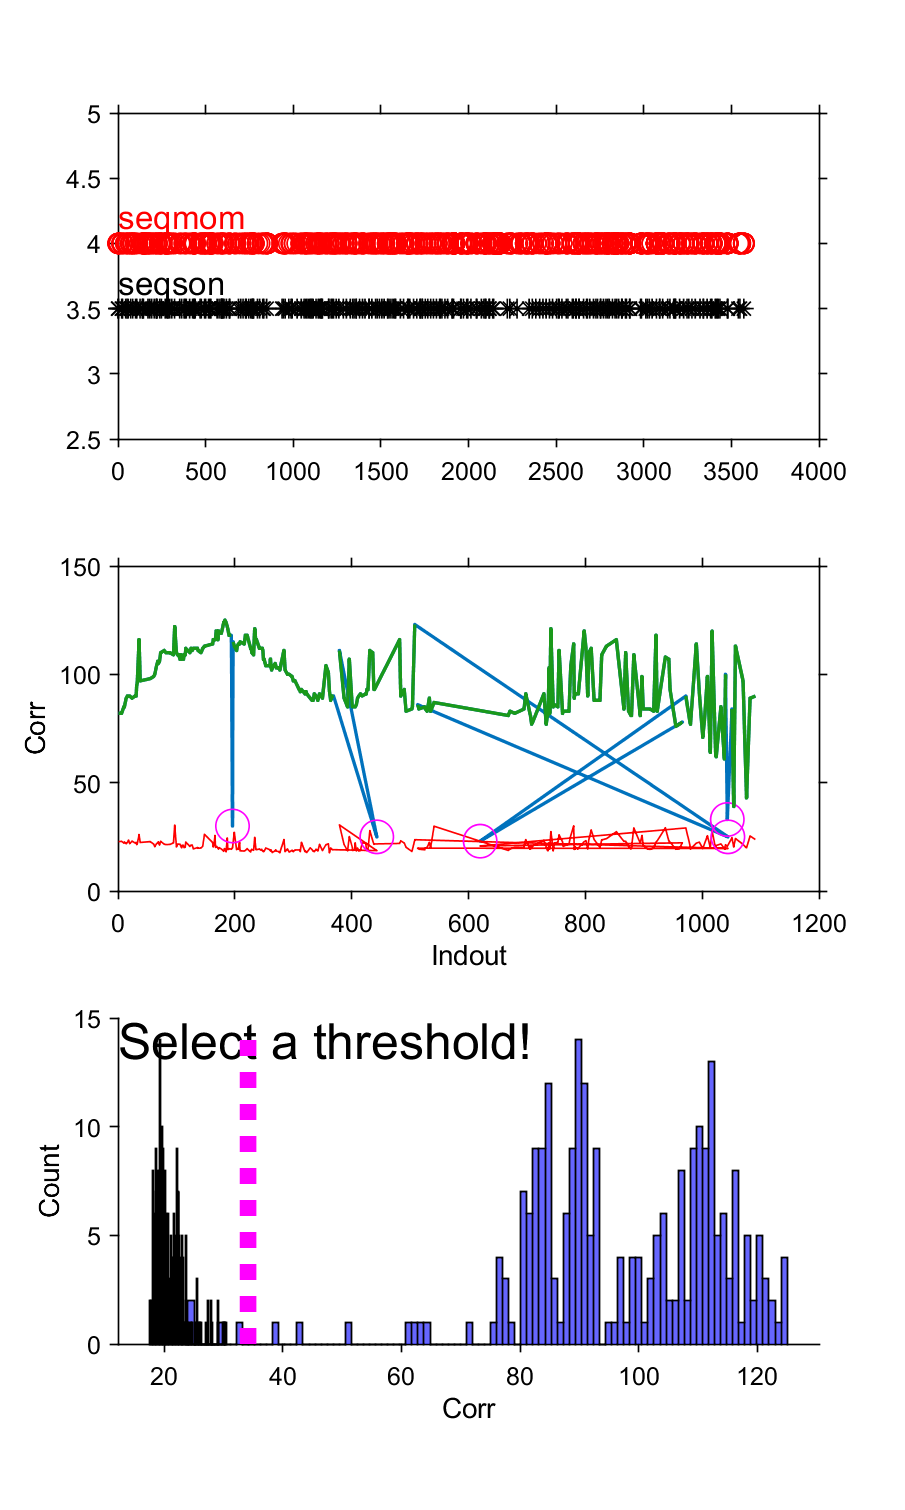


% solve the alignment problem. 
%  Indout = findseqmatchrev(seqmom, seqson, man, toprint, toprintname)
% tricky part is that some events are closed to each other. 
IndStimTimeClusInSoftCode = findseqmatchrev(softcode_times, StimTimesClushat, 0, 1);


TimeOfDLCMapped2Bpod = zeros(1, length(StimTimesClushat));
% This is the "good" softcode time

TimeOfDLCMapped2Bpod(~isnan(IndStimTimeClusInSoftCode)) = softcode_times(IndStimTimeClusInSoftCode(~isnan(IndStimTimeClusInSoftCode)));

figure;
 
hold on
hs(1)=scatter(softcode_times, 4*ones(1, length(softcode_times)), 'o', 'filled', 'markerfacecolor', 'b')

hs =   Scatter with properties:

              XData: [73.8345 75.3512 75.8725 75.9109 76.3726 76.8325 79.5514 80.2517 80.8328 95.2517 100.0317 100.2519 100.3116 118.0716 118.8321 125.5517 126.9113 132.1313 133.7918 146.0116 147.0118 147.2719 147.3119 157.5119 160.2716 160.4521 … ]
              YData: [4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 … ]
              ZData: [1×0 double]
           SizeData: 36
              CData: [0 0.4470 0.7410]
             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: [0 0 1]
          LineWidth: 0.5000

  Show 

hs(2)=scatter(TimeOfDLCMapped2Bpod, 5*ones(1, length(TimeOfDLCMapped2Bpod)), 'o', 'filled', 'markerfacecolor', 'r')

hs =   1×2 Scatter array:

    Scatter    Scatter


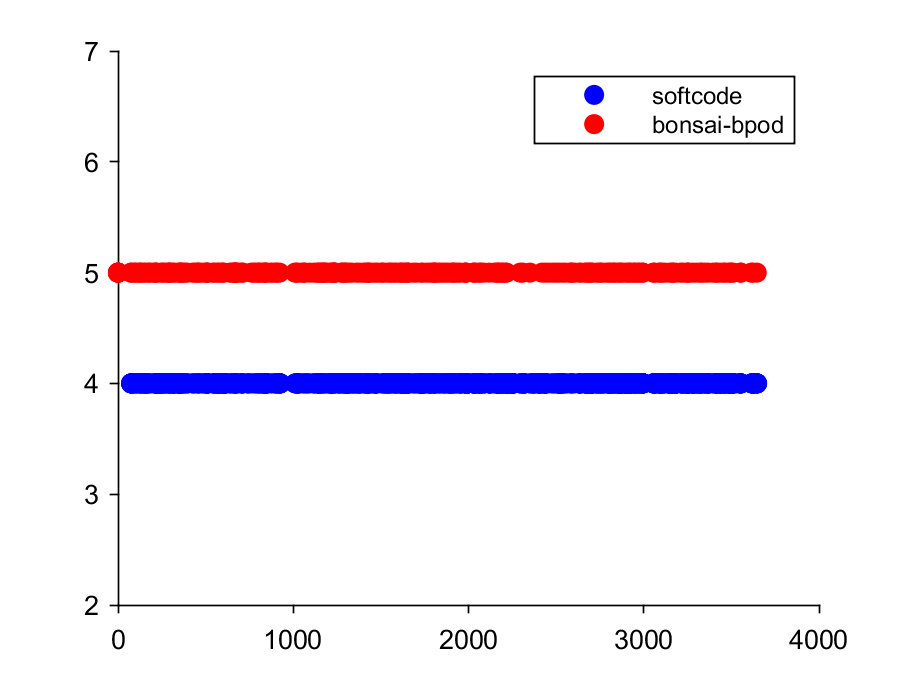

 
legend(hs, 'softcode', 'bonsai-bpod')
set(gca, 'YLim', [2 7])

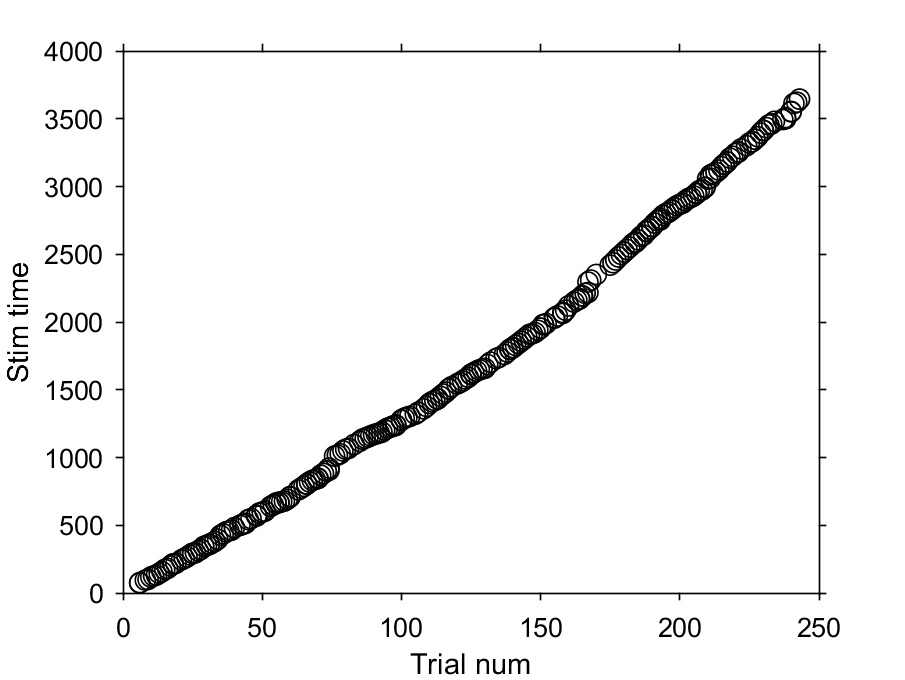


StimTimesClusMapped         =   StimTimesClus(~isnan(IndStimTimeClusInSoftCode)); % time of these triggers in bonsai time
Bpod_StimTimeClus           =   softcode_times(IndStimTimeClusInSoftCode(~isnan(IndStimTimeClusInSoftCode))); % time of these triggers
BpodTrialNum_StimTimeClus   =   softcode_trials(IndStimTimeClusInSoftCode(~isnan(IndStimTimeClusInSoftCode))); % trial number of these triggers

hf3 =figure;
plot(BpodTrialNum_StimTimeClus, Bpod_StimTimeClus, 'ko')
xlabel('Trial num')
ylabel('Stim time')


% Check if this is a non-stim or a stim trial, also, check if the stim
% occurs before press (so it actually counts. it should be because we have
% clustered it such that the paw is still in the air)

TrialsWithDLCTrigger = unique(BpodTrialNum_StimTimeClus); % 

EventMat         =      [];
ApproachTime     =      NaN*ones(1, SessionData.nTrials);
OptoStim         =      -1*ones(1, SessionData.nTrials);
OptoStimTypes    =     cell(SessionData.nTrials, 1);
PressTime        =      NaN*ones(1, SessionData.nTrials); % NaN, no press within 4 sec
DLCTime          =      NaN*ones(1, SessionData.nTrials); 
FrameIdxDCLTime  =      NaN*ones(1, SessionData.nTrials);  % this stores the frame index of each DLC trigger event. 
tFrameDCLTime    =      NaN*ones(1, SessionData.nTrials);  % time of each Bpod-verified DLC frame 
ReleaseTime      =      NaN*ones(1, SessionData.nTrials); 
TriggerTime      =      NaN*ones(1, SessionData.nTrials); % This is the trigger time for the tone (important for video alignment)

% Figure out which signal corresponds to approach
Confirmed           =       0; % We are not sure if BNC2High or BNC2Low is approach signal. 
ApproachSignalType  =       NaN;
for i =1:SessionData.nTrials

    iStates     =      SessionData.RawEvents.Trial{(i)}.States;
    iEvents     =      SessionData.RawEvents.Trial{(i)}.Events;

     if ~isnan(iStates.WaitForApproach(1)) % could be a non-stim trial or a approach stim trial
        if ~isnan(iStates.WaitForPress(1)) % approach detected
            iApproachTime = iStates.WaitForApproach(end);
            if ismember(iApproachTime, iEvents.BNC2High)
                ApproachSignalType = 'BNC2High';
                Confirmed = 1;
            elseif ismember(iApproachTime, iEvents.BNC2Low)
                ApproachSignalType = 'BNC2Low';
                Confirmed = 1;
            end;
        end;
    end;

    if Confirmed 
        break
    end;

end;

for i =1:SessionData.nTrials

    iStates     =      SessionData.RawEvents.Trial{(i)}.States;
    iEvents     =      SessionData.RawEvents.Trial{(i)}.Events;
    t_thistrial =      SessionData.TrialStartTimestamp(i);

    iApproachTime   =    0; % time of approaching the lever
    iDLCTime        =    0; % time of DLC detection just before press
    iPressTime      =    []; % time of lever press
    iOptoStim       =    []; % 0, no stim; 1, optostimulation applied upon approach 2, stim applied up DLC detection
    iReleaseTime    =    0;
    iTriggerTime    =    0;

    % Now check if there is lever press (This now works great)
    if isfield(iEvents, 'AnalogIn1_1') && ismember(iStates.WaitForTrigger(1), iEvents.AnalogIn1_1)% regardless of whether the preceeding state is WaitForPress or WaitForPressStim
        iPressTime = iStates.WaitForTrigger(1);
    elseif iStates.WaitForPress(end) == iStates.WaitForPortExit(1) || iStates.WaitForPressStim(end) == iStates.WaitForPortExit(1)
        iPressTime = 0; % didn't press within 4 sec after WaitForPress
    end

    % Check if there is lever release
    if ~isnan(iStates.WaitForMedTTL(1)) || ~isnan(iStates.WaitForMedTTLStim(1))
        
        iTriggerTime = [iStates.WaitForMedTTL(1) iStates.WaitForMedTTLStim(1)]; 
        iTriggerTime = iTriggerTime(~isnan(iTriggerTime)); % trigger time

        if ~isnan(iStates.Release(1))
            iReleaseTime = iStates.Release(1);
        end;
        % Note that there is no way to know release time from Bpod if it is
        % an incorrect release events
    end;

    if ismember(i, TrialsWithDLCTrigger)
        DLCTrial =1;
    else
        DLCTrial = 0;
    end;

    if ~isnan(iStates.WaitForApproach(1)) % could be a non-stim trial or a approach stim trial
        if ~isnan(iStates.WaitForPress(1)) || ~isnan(iStates.WaitForPressStim(1))% approach detected
            iApproachTime = iStates.WaitForApproach(end);
        else
            iApproachTime = 0;
        end;

        % Check if there is opto-stim (Note that if a state starts with WaitForApproach, it cannot be a DLC-Stim trial)
        if ~isnan(iStates.WaitForPressStim(1))
            iOptoStim = 1;
        elseif ~isnan(iStates.WaitForPress(1))
            iOptoStim = 0;
        end;

        % Check if there is a DLC signal
        if DLCTrial
            tDLCTemp = iEvents.SoftCode6;
            [tDLCTempOrg, indtDLC] = intersect(tDLCTemp+t_thistrial, TimeOfDLCMapped2Bpod);
            tDLCTemp = tDLCTemp(indtDLC);
            if ~isempty(tDLCTempOrg)
                if iPressTime ~= 0 % is there a press signal
                    if any(tDLCTemp < iPressTime)                       
                        iDLCTime = tDLCTemp(find(tDLCTemp < iPressTime, 1, 'first')); % select the first DLC detection of this trial 
                        % (note that bonsai may send a whole bunch of trigger signals to bpod with continuous body detection)
                    end;
                else % no press signal
                    if any(tDLCTemp < iStates.WaitForPortExit(1) & tDLCTemp > iStates.WaitForApproach(end)); % No press signal
                        iDLCTime = tDLCTemp(find(tDLCTemp>iStates.WaitForApproach(1), 1, 'first'));
                    end;
                end;
            else
                figure; plot(TimeOfDLCMapped2Bpod, 5, 'ko')
                hold on
                plot(tDLCTemp+t_thistrial, 5, 'r*')
                hold off
            end;
        end;
    end;

    if ~isnan(iStates.WaitForDLC(1)) % DLC trial although DLC might not be detected
        % Extract approach signal in these trials (note that there is no
        % explicit WaitForApproach state available.
        if isfield(iEvents, ApproachSignalType) % approach detected
            if iPressTime~=0
                if any(eval(['iEvents.' ApproachSignalType]) < iPressTime); % there is an approach signal before press signal
                    ApproachTemp = eval(['iEvents.' ApproachSignalType]); %#ok<EVLDOT> % take it
                    iApproachTime = ApproachTemp(find(ApproachTemp < iPressTime, 1, 'last'));
                end;
            else
                if any(eval(['iEvents.' ApproachSignalType]) < iStates.WaitForPortExit(1)); % No press signal
                    ApproachTemp = eval(['iEvents.' ApproachSignalType]); %#ok<EVLDOT> % take it
                    iApproachTime = ApproachTemp(find(ApproachTemp < iStates.WaitForPortExit(1), 1, 'last'));
                end;
            end;
        end;


        % Is there a correct DLC signal (e.g., in the correct cluster)?
        if DLCTrial
            %             This trial likely looks something like this:
            %                  TrialStart: [0 0.5000]
            %                  WaitForDLC: [0.5000 6.4682]
            %                     Masking: [6.4682 6.4692]
            %            WaitForPressStim: [6.4692 8.0874]
            %              WaitForTrigger: [8.0874 9.2874]
            %               WaitForMedTTL: [9.2874 9.5067]
            %                     Release: [9.5067 9.5077]
            %     CheckForAdditionalPulse: [9.5077 9.5327]
            %           WaitForPokedInLow: [9.5327 10.6324]
            %               WaterDelayLow: [10.6324 10.7324]
            %           RewardDeliveryLow: [10.7324 10.8824]
            %                    Drinking: [10.8824 12.5759]
            %               DrinkingGrace: [12.5759 13.0759]
            %             WaitForPortExit: [13.0759 13.2759]
            if ismember(iStates.WaitForDLC(2), iEvents.SoftCode6) % DLC signal is at the right place
                if ismember(iStates.WaitForDLC(2)+t_thistrial, TimeOfDLCMapped2Bpod)
                    iDLCTime = iStates.WaitForDLC(2);
                    % Check if there is opto-stim
                    if ~isnan(iStates.WaitForPressStim(1))
                        iOptoStim = 2;
                    end;
                else
%                     figure(10); clf
%                     plot(iStates.WaitForDLC(2)+t_thistrial, 5, 'ro');
%                     hold on
%                     plot(TimeOfDLCMapped2Bpod, 5, 'bx')
%                     hold off
                end;

            end;
        end;
    end;


    if ~isempty(iOptoStim)
        OptoStim(i) = iOptoStim;
        switch iOptoStim
            case 0
                OptoStimTypes{i} = 'NoStim';
            case 1
                OptoStimTypes{i} = 'Stim_Approach';
            case 2
                OptoStimTypes{i} = 'Stim_DLC';
        end
    end;

    if iApproachTime~=0
        ApproachTime(i) = iApproachTime + t_thistrial;
    else
        ApproachTime(i) = iApproachTime;
    end;

    if iTriggerTime ~= 0
        TriggerTime(i) = iTriggerTime +  t_thistrial;
    else
        TriggerTime(i) = iTriggerTime;
    end;

    if iPressTime ~=0
        PressTime(i) = iPressTime + t_thistrial;
        
    else
        PressTime(i) = iPressTime;
    end;

    if iDLCTime ~=0
        DLCTime(i) = iDLCTime + t_thistrial;
        % find out the trigger times
        ind_DLC = find(TimeOfDLCMapped2Bpod == iDLCTime+t_thistrial);
        thisStimTimeClus = StimTimesClus(ind_DLC);
        display(thisStimTimeClus)
        indPosData =  find(PosData.StimTime(:, 1)==thisStimTimeClus);
        if ~isempty(indPosData)
            FrameIdxDCLTime(i)    =    indPosData;
            tFrameDCLTime(i)      =    thisStimTimeClus;    
        else
            error('Check')
        end;
    else
        DLCTime(i) = iDLCTime;
    end;

    if iReleaseTime ~=0
        ReleaseTime(i) = iReleaseTime + t_thistrial;
    else
        ReleaseTime(i) = iReleaseTime;
    end;

    if iPressTime~=0 && iDLCTime ~=0
        ilatency = iPressTime - iDLCTime
        sprintf('DLC to press latency %2.2f ms', ilatency*1000)
        if ilatency<0.100
            iStates
            []
        end;
    end;

end;

thisStimTimeClus = 5.3593e+04

ilatency = 0.2187

ans = 'DLC to press latency 218.70 ms'

thisStimTimeClus = 5.3615e+04

ilatency = 0.1906

ans = 'DLC to press latency 190.60 ms'

thisStimTimeClus = 5.3620e+04

thisStimTimeClus = 5.3638e+04

ilatency = 0.5298

ans = 'DLC to press latency 529.80 ms'

thisStimTimeClus = 5.3645e+04

ilatency = 0.1998

ans = 'DLC to press latency 199.80 ms'

thisStimTimeClus = 5.3652e+04

ilatency = 0.1102

ans = 'DLC to press latency 110.20 ms'

thisStimTimeClus = 5.3666e+04

ilatency = 1.2390

ans = 'DLC to press latency 1239.00 ms'

thisStimTimeClus = 5.3677e+04

ilatency = 3.6078

ans = 'DLC to press latency 3607.80 ms'

thisStimTimeClus = 5.3694e+04

ilatency = 0.2071

ans = 'DLC to press latency 207.10 ms'

thisStimTimeClus = 5.3701e+04

ilatency = 0.3066

ans = 'DLC to press latency 306.60 ms'

thisStimTimeClus = 5.3719e+04

ilatency = 1.1065

ans = 'DLC to press latency 1106.50 ms'

thisStimTimeClus = 5.3732e+04

ilatency = 1.6060

ans = 'DLC to press latency 1606.00 ms'

thisStimTimeClus = 5.3739e+04

ilatency = 1.5642

ans = 'DLC to press latency 1564.20 ms'

thisStimTimeClus = 5.3765e+04

ilatency = 1.0735

ans = 'DLC to press latency 1073.50 ms'

thisStimTimeClus = 5.3775e+04

ilatency = 0.1645

ans = 'DLC to press latency 164.50 ms'

thisStimTimeClus = 5.3786e+04

ilatency = 1.3133

ans = 'DLC to press latency 1313.30 ms'

thisStimTimeClus = 5.3800e+04

ilatency = 0.7632

ans = 'DLC to press latency 763.20 ms'

thisStimTimeClus = 5.3812e+04

ilatency = 0.5635

ans = 'DLC to press latency 563.50 ms'

thisStimTimeClus = 5.3816e+04

ilatency = 1.1334

ans = 'DLC to press latency 1133.40 ms'

thisStimTimeClus = 5.3831e+04

ilatency = 1.2720

ans = 'DLC to press latency 1272.00 ms'

thisStimTimeClus = 5.3841e+04

thisStimTimeClus = 5.3863e+04

ilatency = 0.3115

ans = 'DLC to press latency 311.50 ms'

thisStimTimeClus = 5.3870e+04

ilatency = 1.8597

ans = 'DLC to press latency 1859.70 ms'

thisStimTimeClus = 5.3878e+04

ilatency = 0.1473

ans = 'DLC to press latency 147.30 ms'

thisStimTimeClus = 5.3889e+04

ilatency = 0.2786

ans = 'DLC to press latency 278.60 ms'

thisStimTimeClus = 5.3900e+04

ilatency = 0.6894

ans = 'DLC to press latency 689.40 ms'

thisStimTimeClus = 5.3916e+04

ilatency = 0.4688

ans = 'DLC to press latency 468.80 ms'

thisStimTimeClus = 5.3946e+04

ilatency = 0.1866

ans = 'DLC to press latency 186.60 ms'

thisStimTimeClus = 5.3957e+04

ilatency = 1.1469

ans = 'DLC to press latency 1146.90 ms'

thisStimTimeClus = 5.3971e+04

ilatency = 1.6033

ans = 'DLC to press latency 1603.30 ms'

thisStimTimeClus = 5.3978e+04

ilatency = 0.2751

ans = 'DLC to press latency 275.10 ms'

thisStimTimeClus = 5.3984e+04

ilatency = 0.1856

ans = 'DLC to press latency 185.60 ms'

thisStimTimeClus = 5.4002e+04

thisStimTimeClus = 5.4019e+04

ilatency = 0.3640

ans = 'DLC to press latency 364.00 ms'

thisStimTimeClus = 5.4026e+04

ilatency = 2.4633

ans = 'DLC to press latency 2463.30 ms'

thisStimTimeClus = 5.4034e+04

ilatency = 1.3524

ans = 'DLC to press latency 1352.40 ms'

thisStimTimeClus = 5.4062e+04

ilatency = 0.2420

ans = 'DLC to press latency 242.00 ms'

thisStimTimeClus = 5.4069e+04

ilatency = 0.4729

ans = 'DLC to press latency 472.90 ms'

thisStimTimeClus = 5.4094e+04

ilatency = 0.7777

ans = 'DLC to press latency 777.70 ms'

thisStimTimeClus = 5.4110e+04

ilatency = 0.3787

ans = 'DLC to press latency 378.70 ms'

thisStimTimeClus = 5.4117e+04

ilatency = 1.0686

ans = 'DLC to press latency 1068.60 ms'

thisStimTimeClus = 5.4124e+04

ilatency = 0.5998

ans = 'DLC to press latency 599.80 ms'

thisStimTimeClus = 5.4159e+04

ilatency = 0.3380

ans = 'DLC to press latency 338.00 ms'

thisStimTimeClus = 5.4170e+04

ilatency = 0.2477

ans = 'DLC to press latency 247.70 ms'

thisStimTimeClus = 5.4182e+04

thisStimTimeClus = 5.4186e+04

ilatency = 1.0065

ans = 'DLC to press latency 1006.50 ms'

thisStimTimeClus = 5.4193e+04

thisStimTimeClus = 5.4199e+04

ilatency = 0.3137

ans = 'DLC to press latency 313.70 ms'

thisStimTimeClus = 5.4212e+04

ilatency = 0.1766

ans = 'DLC to press latency 176.60 ms'

thisStimTimeClus = 5.4228e+04

ilatency = 0.8149

ans = 'DLC to press latency 814.90 ms'

thisStimTimeClus = 5.4281e+04

ilatency = 0.3538

ans = 'DLC to press latency 353.80 ms'

thisStimTimeClus = 5.4294e+04

ilatency = 1.1119

ans = 'DLC to press latency 1111.90 ms'

thisStimTimeClus = 5.4307e+04

ilatency = 1.3818

ans = 'DLC to press latency 1381.80 ms'

thisStimTimeClus = 5.4322e+04

ilatency = 1.8494

ans = 'DLC to press latency 1849.40 ms'

thisStimTimeClus = 5.4339e+04

ilatency = 0.2311

ans = 'DLC to press latency 231.10 ms'

thisStimTimeClus = 5.4351e+04

ilatency = 0.4102

ans = 'DLC to press latency 410.20 ms'

thisStimTimeClus = 5.4358e+04

ilatency = 1.2393

ans = 'DLC to press latency 1239.30 ms'

thisStimTimeClus = 5.4364e+04

ilatency = 3.7900

ans = 'DLC to press latency 3790.00 ms'

thisStimTimeClus = 5.4390e+04

ilatency = 0.5085

ans = 'DLC to press latency 508.50 ms'

thisStimTimeClus = 5.4402e+04

ilatency = 1.6883

ans = 'DLC to press latency 1688.30 ms'

thisStimTimeClus = 5.4419e+04

thisStimTimeClus = 5.4425e+04

thisStimTimeClus = 5.4530e+04

ilatency = 0.3429

ans = 'DLC to press latency 342.90 ms'

thisStimTimeClus = 5.4538e+04

ilatency = 0.3022

ans = 'DLC to press latency 302.20 ms'

thisStimTimeClus = 5.4547e+04

ilatency = 0.9716

ans = 'DLC to press latency 971.60 ms'

thisStimTimeClus = 5.4568e+04

ilatency = 0.9707

ans = 'DLC to press latency 970.70 ms'

thisStimTimeClus = 5.4581e+04

ilatency = 0.1906

ans = 'DLC to press latency 190.60 ms'

thisStimTimeClus = 5.4587e+04

ilatency = 0.2894

ans = 'DLC to press latency 289.40 ms'

thisStimTimeClus = 5.4616e+04

ilatency = 1.7087

ans = 'DLC to press latency 1708.70 ms'

thisStimTimeClus = 5.4639e+04

ilatency = 0.8389

ans = 'DLC to press latency 838.90 ms'

thisStimTimeClus = 5.4655e+04

ilatency = 0.2270

ans = 'DLC to press latency 227.00 ms'

thisStimTimeClus = 5.4663e+04

ilatency = 1.1065

ans = 'DLC to press latency 1106.50 ms'

thisStimTimeClus = 5.4671e+04

ilatency = 0.2673

ans = 'DLC to press latency 267.30 ms'

thisStimTimeClus = 5.4680e+04

ilatency = 0.2257

ans = 'DLC to press latency 225.70 ms'

thisStimTimeClus = 5.4688e+04

ilatency = 0.2162

ans = 'DLC to press latency 216.20 ms'

thisStimTimeClus = 5.4694e+04

ilatency = 0.3059

ans = 'DLC to press latency 305.90 ms'

thisStimTimeClus = 5.4701e+04

ilatency = 0.2150

ans = 'DLC to press latency 215.00 ms'

thisStimTimeClus = 5.4707e+04

ilatency = 0.3949

ans = 'DLC to press latency 394.90 ms'

thisStimTimeClus = 5.4723e+04

ilatency = 0.4325

ans = 'DLC to press latency 432.50 ms'

thisStimTimeClus = 5.4736e+04

ilatency = 1.2944

ans = 'DLC to press latency 1294.40 ms'

thisStimTimeClus = 5.4743e+04

ilatency = 0.2634

ans = 'DLC to press latency 263.40 ms'

thisStimTimeClus = 5.4751e+04

ilatency = 1.3974

ans = 'DLC to press latency 1397.40 ms'

thisStimTimeClus = 5.4757e+04

ilatency = 0.4736

ans = 'DLC to press latency 473.60 ms'

thisStimTimeClus = 5.4795e+04

ilatency = 0.3314

ans = 'DLC to press latency 331.40 ms'

thisStimTimeClus = 5.4809e+04

ilatency = 1.8204

ans = 'DLC to press latency 1820.40 ms'

thisStimTimeClus = 5.4817e+04

ilatency = 0.2003

ans = 'DLC to press latency 200.30 ms'

thisStimTimeClus = 5.4823e+04

ilatency = 0.1607

ans = 'DLC to press latency 160.70 ms'

thisStimTimeClus = 5.4839e+04

thisStimTimeClus = 5.4854e+04

ilatency = 0.2387

ans = 'DLC to press latency 238.70 ms'

thisStimTimeClus = 5.4879e+04

ilatency = 0.4484

ans = 'DLC to press latency 448.40 ms'

thisStimTimeClus = 5.4897e+04

ilatency = 0.3467

ans = 'DLC to press latency 346.70 ms'

thisStimTimeClus = 5.4918e+04

ilatency = 1.3753

ans = 'DLC to press latency 1375.30 ms'

thisStimTimeClus = 5.4932e+04

ilatency = 1.2262

ans = 'DLC to press latency 1226.20 ms'

thisStimTimeClus = 5.4941e+04

ilatency = 1.2448

ans = 'DLC to press latency 1244.80 ms'

thisStimTimeClus = 5.4952e+04

ilatency = 0.2654

ans = 'DLC to press latency 265.40 ms'

thisStimTimeClus = 5.4972e+04

ilatency = 0.3442

ans = 'DLC to press latency 344.20 ms'

thisStimTimeClus = 5.4989e+04

ilatency = 2.0927

ans = 'DLC to press latency 2092.70 ms'

thisStimTimeClus = 5.5003e+04

ilatency = 2.2905

ans = 'DLC to press latency 2290.50 ms'

thisStimTimeClus = 5.5026e+04

ilatency = 2.0289

ans = 'DLC to press latency 2028.90 ms'

thisStimTimeClus = 5.5042e+04

ilatency = 0.3506

ans = 'DLC to press latency 350.60 ms'

thisStimTimeClus = 5.5063e+04

ilatency = 0.3297

ans = 'DLC to press latency 329.70 ms'

thisStimTimeClus = 5.5073e+04

ilatency = 0.3594

ans = 'DLC to press latency 359.40 ms'

thisStimTimeClus = 5.5085e+04

ilatency = 1.6791

ans = 'DLC to press latency 1679.10 ms'

thisStimTimeClus = 5.5099e+04

ilatency = 0.3194

ans = 'DLC to press latency 319.40 ms'

thisStimTimeClus = 5.5112e+04

ilatency = 0.4070

ans = 'DLC to press latency 407.00 ms'

thisStimTimeClus = 5.5132e+04

ilatency = 0.4168

ans = 'DLC to press latency 416.80 ms'

thisStimTimeClus = 5.5157e+04

ilatency = 0.2458

ans = 'DLC to press latency 245.80 ms'

thisStimTimeClus = 5.5167e+04

ilatency = 0.2639

ans = 'DLC to press latency 263.90 ms'

thisStimTimeClus = 5.5174e+04

ilatency = 0.3051

ans = 'DLC to press latency 305.10 ms'

thisStimTimeClus = 5.5178e+04

ilatency = 1.5898

ans = 'DLC to press latency 1589.80 ms'

thisStimTimeClus = 5.5205e+04

ilatency = 0.5044

ans = 'DLC to press latency 504.40 ms'

thisStimTimeClus = 5.5223e+04

ilatency = 0.2731

ans = 'DLC to press latency 273.10 ms'

thisStimTimeClus = 5.5258e+04

ilatency = 0.5218

ans = 'DLC to press latency 521.80 ms'

thisStimTimeClus = 5.5280e+04

ilatency = 1.4114

ans = 'DLC to press latency 1411.40 ms'

thisStimTimeClus = 5.5298e+04

ilatency = 1.0897

ans = 'DLC to press latency 1089.70 ms'

thisStimTimeClus = 5.5317e+04

ilatency = 2.7592

ans = 'DLC to press latency 2759.20 ms'

thisStimTimeClus = 5.5329e+04

ilatency = 0.6493

ans = 'DLC to press latency 649.30 ms'

thisStimTimeClus = 5.5347e+04

ilatency = 0.3579

ans = 'DLC to press latency 357.90 ms'

thisStimTimeClus = 5.5361e+04

ilatency = 0.3970

ans = 'DLC to press latency 397.00 ms'

thisStimTimeClus = 5.5378e+04

ilatency = 1.8363

ans = 'DLC to press latency 1836.30 ms'

thisStimTimeClus = 5.5393e+04

ilatency = 1.1155

ans = 'DLC to press latency 1115.50 ms'

thisStimTimeClus = 5.5411e+04

ilatency = 0.2357

ans = 'DLC to press latency 235.70 ms'

thisStimTimeClus = 5.5433e+04

ilatency = 1.0345

ans = 'DLC to press latency 1034.50 ms'

thisStimTimeClus = 5.5442e+04

ilatency = 0.4131

ans = 'DLC to press latency 413.10 ms'

thisStimTimeClus = 5.5459e+04

ilatency = 1.3632

ans = 'DLC to press latency 1363.20 ms'

thisStimTimeClus = 5.5474e+04

ilatency = 1.0501

ans = 'DLC to press latency 1050.10 ms'

thisStimTimeClus = 5.5500e+04

thisStimTimeClus = 5.5508e+04

thisStimTimeClus = 5.5565e+04

ilatency = 1.5183

ans = 'DLC to press latency 1518.30 ms'

thisStimTimeClus = 5.5583e+04

ilatency = 4.9077

ans = 'DLC to press latency 4907.70 ms'

thisStimTimeClus = 5.5607e+04

ilatency = 1.8473

ans = 'DLC to press latency 1847.30 ms'

thisStimTimeClus = 5.5638e+04

ilatency = 0.3540

ans = 'DLC to press latency 354.00 ms'

thisStimTimeClus = 5.5667e+04

ilatency = 0.7120

ans = 'DLC to press latency 712.00 ms'

thisStimTimeClus = 5.5681e+04

ilatency = 1.0415

ans = 'DLC to press latency 1041.50 ms'

thisStimTimeClus = 5.5689e+04

ilatency = 5.1513

ans = 'DLC to press latency 5151.30 ms'

thisStimTimeClus = 5.5711e+04

ilatency = 0.4017

ans = 'DLC to press latency 401.70 ms'

thisStimTimeClus = 5.5732e+04

ilatency = 0.5014

ans = 'DLC to press latency 501.40 ms'

thisStimTimeClus = 5.5737e+04

ilatency = 79.5658

ans = 'DLC to press latency 79565.80 ms'

thisStimTimeClus = 5.5829e+04

ilatency = 1.3575

ans = 'DLC to press latency 1357.50 ms'

thisStimTimeClus = 5.5871e+04

ilatency = 1.0364

ans = 'DLC to press latency 1036.40 ms'

thisStimTimeClus = 5.5939e+04

ilatency = 0.1839

ans = 'DLC to press latency 183.90 ms'

thisStimTimeClus = 5.5978e+04

ilatency = 0.3216

ans = 'DLC to press latency 321.60 ms'

thisStimTimeClus = 5.6000e+04

ilatency = 0.4506

ans = 'DLC to press latency 450.60 ms'

thisStimTimeClus = 5.6018e+04

ilatency = 0.3596

ans = 'DLC to press latency 359.60 ms'

thisStimTimeClus = 5.6037e+04

ilatency = 1.7367

ans = 'DLC to press latency 1736.70 ms'

thisStimTimeClus = 5.6055e+04

ilatency = 0.1385

ans = 'DLC to press latency 138.50 ms'

thisStimTimeClus = 5.6073e+04

ilatency = 1.8279

ans = 'DLC to press latency 1827.90 ms'

thisStimTimeClus = 5.6096e+04

thisStimTimeClus = 5.6107e+04

ilatency = 2.0846

ans = 'DLC to press latency 2084.60 ms'

thisStimTimeClus = 5.6126e+04

ilatency = 0.7451

ans = 'DLC to press latency 745.10 ms'

thisStimTimeClus = 5.6152e+04

thisStimTimeClus = 5.6161e+04

ilatency = 0.3541

ans = 'DLC to press latency 354.10 ms'

thisStimTimeClus = 5.6186e+04

ilatency = 3.9923

ans = 'DLC to press latency 3992.30 ms'

thisStimTimeClus = 5.6206e+04

ilatency = 0.0822

ans = 'DLC to press latency 82.20 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 9.2660]
                    Masking: [9.2660 9.2670]
               WaitForPress: [9.2670 9.9196]
             WaitForTrigger: [9.9196 11.4196]
              WaitForMedTTL: [11.4196 11.6488]
                    Release: [11.6488 11.6498]
    CheckForAdditionalPulse: [11.6498 11.6688]
         WaitForPokedInHigh: [11.6688 13.5366]
             WaterDelayHigh: [13.5366 13.6366]
         RewardDeliveryHigh: [13.6366 13.8316]
                   Drinking: [13.8316 15.7292]
              DrinkingGrace: [15.7292 16.2292]
            WaitForPortExit: [16.2292 16.4292]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
              


ans =

     []



thisStimTimeClus = 5.6223e+04

ilatency = 0.5507

ans = 'DLC to press latency 550.70 ms'

thisStimTimeClus = 5.6250e+04

ilatency = 0.4100

ans = 'DLC to press latency 410.00 ms'

thisStimTimeClus = 5.6267e+04

ilatency = 0.1297

ans = 'DLC to press latency 129.70 ms'

thisStimTimeClus = 5.6272e+04

ilatency = 13.8175

ans = 'DLC to press latency 13817.50 ms'

thisStimTimeClus = 5.6321e+04

ilatency = 1.3766

ans = 'DLC to press latency 1376.60 ms'

thisStimTimeClus = 5.6330e+04

ilatency = 0.0868

ans = 'DLC to press latency 86.80 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 3.7733]
                    Masking: [3.7733 3.7743]
               WaitForPress: [3.7743 4.5120]
             WaitForTrigger: [4.5120 5.2620]
              WaitForMedTTL: [5.2620 5.6112]
                    Release: [5.6112 5.6122]
    CheckForAdditionalPulse: [5.6122 5.6372]
          WaitForPokedInLow: [5.6372 7.5460]
              WaterDelayLow: [7.5460 7.6460]
          RewardDeliveryLow: [7.6460 7.7960]
                   Drinking: [7.7960 9.4320]
              DrinkingGrace: [9.4320 9.9320]
            WaitForPortExit: [9.9320 10.1320]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               InvalidEntry: [Na


ans =

     []



thisStimTimeClus = 5.6364e+04

ilatency = 0.0251

ans = 'DLC to press latency 25.10 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 10.9241]
                    Masking: [10.9241 10.9251]
               WaitForPress: [10.9251 11.5547]
             WaitForTrigger: [11.5547 12.3047]
              WaitForMedTTL: [12.3047 12.5543]
                    Release: [12.5543 12.5553]
    CheckForAdditionalPulse: [12.5553 12.5743]
         WaitForPokedInHigh: [12.5743 14.1961]
             WaterDelayHigh: [14.1961 14.2961]
         RewardDeliveryHigh: [14.2961 14.4911]
                   Drinking: [14.4911 16.0855]
              DrinkingGrace: [16.0855 16.5855]
            WaitForPortExit: [16.5855 16.7855]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
        


ans =

     []



thisStimTimeClus = 5.6378e+04

ilatency = 0.1050

ans = 'DLC to press latency 105.00 ms'

thisStimTimeClus = 5.6389e+04

ilatency = 0.3239

ans = 'DLC to press latency 323.90 ms'

thisStimTimeClus = 5.6397e+04

ilatency = 0.3636

ans = 'DLC to press latency 363.60 ms'

thisStimTimeClus = 5.6415e+04

ilatency = 1.2021

ans = 'DLC to press latency 1202.10 ms'

thisStimTimeClus = 5.6430e+04

ilatency = 0.2214

ans = 'DLC to press latency 221.40 ms'

thisStimTimeClus = 5.6439e+04

ilatency = 0.1119

ans = 'DLC to press latency 111.90 ms'

thisStimTimeClus = 5.6450e+04

ilatency = 0.7913

ans = 'DLC to press latency 791.30 ms'

thisStimTimeClus = 5.6468e+04

ilatency = 0.0795

ans = 'DLC to press latency 79.50 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 9.1618]
                    Masking: [9.1618 9.1628]
               WaitForPress: [9.1628 9.7971]
             WaitForTrigger: [9.7971 11.2972]
              WaitForMedTTL: [11.2972 11.6869]
                    Release: [11.6869 11.6879]
    CheckForAdditionalPulse: [11.6879 11.7129]
          WaitForPokedInLow: [11.7129 13.9964]
              WaterDelayLow: [13.9964 14.0964]
          RewardDeliveryLow: [14.0964 14.2464]
                   Drinking: [2×2 double]
              DrinkingGrace: [2×2 double]
            WaitForPortExit: [16.6900 16.8900]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               InvalidEn


ans =

     []



thisStimTimeClus = 5.6494e+04

ilatency = 0.4498

ans = 'DLC to press latency 449.80 ms'

thisStimTimeClus = 5.6513e+04

ilatency = 0.0361

ans = 'DLC to press latency 36.10 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 8.7177]
                    Masking: [8.7177 8.7187]
           WaitForPressStim: [8.7187 11.5906]
             WaitForTrigger: [11.5906 12.3406]
              WaitForMedTTL: [12.3406 12.5901]
                    Release: [12.5901 12.5911]
    CheckForAdditionalPulse: [12.5911 12.6101]
         WaitForPokedInHigh: [12.6101 14.3600]
             WaterDelayHigh: [14.3600 14.4600]
         RewardDeliveryHigh: [14.4600 14.6550]
                   Drinking: [14.6550 16.6550]
            WaitForPortExit: [16.6550 16.8550]
                 WaitForDLC: [NaN NaN]
               WaitForPress: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               InvalidEntry: [NaN NaN]
                  Br


ans =

     []



thisStimTimeClus = 5.6580e+04

ilatency = 26.0246

ans = 'DLC to press latency 26024.60 ms'

thisStimTimeClus = 5.6614e+04

ilatency = 0.3135

ans = 'DLC to press latency 313.50 ms'

thisStimTimeClus = 5.6625e+04

ilatency = 0.4231

ans = 'DLC to press latency 423.10 ms'

thisStimTimeClus = 5.6641e+04

ilatency = 0.8234

ans = 'DLC to press latency 823.40 ms'

thisStimTimeClus = 5.6666e+04

ilatency = 0.2021

ans = 'DLC to press latency 202.10 ms'

thisStimTimeClus = 5.6684e+04

ilatency = 0.0013

ans = 'DLC to press latency 1.30 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 10.1728]
                    Masking: [10.1728 10.1738]
               WaitForPress: [10.1738 10.7254]
             WaitForTrigger: [10.7254 11.4754]
              WaitForMedTTL: [11.4754 11.6948]
                    Release: [11.6948 11.6958]
    CheckForAdditionalPulse: [11.6958 11.7148]
         WaitForPokedInHigh: [11.7148 13.6648]
             WaterDelayHigh: [13.6648 13.7648]
         RewardDeliveryHigh: [13.7648 13.9598]
                   Drinking: [13.9598 15.9598]
            WaitForPortExit: [15.9598 16.1598]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               InvalidEntry: [NaN NaN]
                


ans =

     []



thisStimTimeClus = 5.6702e+04

ilatency = 0.3302

ans = 'DLC to press latency 330.20 ms'

thisStimTimeClus = 5.6730e+04

ilatency = 0.3598

ans = 'DLC to press latency 359.80 ms'

thisStimTimeClus = 5.6773e+04

ilatency = 0.5284

ans = 'DLC to press latency 528.40 ms'

thisStimTimeClus = 5.6821e+04

ilatency = 0.1844

ans = 'DLC to press latency 184.40 ms'

thisStimTimeClus = 5.6841e+04

ilatency = 1.3947

ans = 'DLC to press latency 1394.70 ms'

thisStimTimeClus = 5.6850e+04

ilatency = 0.3141

ans = 'DLC to press latency 314.10 ms'

thisStimTimeClus = 5.6868e+04

ilatency = 0.6640

ans = 'DLC to press latency 664.00 ms'

thisStimTimeClus = 5.6887e+04

ilatency = 1.6229

ans = 'DLC to press latency 1622.90 ms'

thisStimTimeClus = 5.6914e+04

ilatency = 0.3815

ans = 'DLC to press latency 381.50 ms'

thisStimTimeClus = 5.6933e+04

ilatency = 0.0404

ans = 'DLC to press latency 40.40 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 10.1816]
                    Masking: [10.1816 10.1826]
               WaitForPress: [10.1826 10.8089]
             WaitForTrigger: [10.8089 12.3089]
              WaitForMedTTL: [12.3089 12.5684]
                    Release: [12.5684 12.5694]
    CheckForAdditionalPulse: [12.5694 12.5884]
         WaitForPokedInHigh: [12.5884 15.0461]
             WaterDelayHigh: [15.0461 15.1461]
         RewardDeliveryHigh: [15.1461 15.3411]
                   Drinking: [15.3411 17.3411]
            WaitForPortExit: [17.3411 17.5411]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               InvalidEntry: [NaN NaN]
                


ans =

     []



thisStimTimeClus = 5.6955e+04

ilatency = 0.6695

ans = 'DLC to press latency 669.50 ms'

thisStimTimeClus = 5.7001e+04

thisStimTimeClus = 5.7014e+04

thisStimTimeClus = 5.7019e+04

ilatency = 9.9763

ans = 'DLC to press latency 9976.30 ms'

thisStimTimeClus = 5.7071e+04

ilatency = 0.3442

ans = 'DLC to press latency 344.20 ms'

thisStimTimeClus = 5.7133e+04

ilatency = 0.3929

ans = 'DLC to press latency 392.90 ms'

thisStimTimeClus = 5.7143e+04

ilatency = 0.8523

ans = 'DLC to press latency 852.30 ms'

thisStimTimeClus = 5.7164e+04

ilatency = 0.0910

ans = 'DLC to press latency 91.00 ms'

iStates = struct with fields:
                 TrialStart: [0 0.5000]
            WaitForApproach: [0.5000 13.5423]
                    Masking: [13.5423 13.5433]
               WaitForPress: [13.5433 14.3981]
             WaitForTrigger: [14.3981 15.8981]
              WaitForMedTTL: [15.8981 16.2474]
                    Release: [16.2474 16.2484]
    CheckForAdditionalPulse: [16.2484 16.2734]
          WaitForPokedInLow: [16.2734 18.6381]
              WaterDelayLow: [18.6381 18.7381]
          RewardDeliveryLow: [18.7381 18.8881]
                   Drinking: [2×2 double]
              DrinkingGrace: [2×2 double]
            WaitForPortExit: [21.4495 21.6495]
                 WaitForDLC: [NaN NaN]
           WaitForPressStim: [NaN NaN]
               BadPortEntry: [NaN NaN]
         WaitForTriggerStim: [NaN NaN]
          WaitForMedTTLStim: [NaN NaN]
                ReleaseStim: [NaN NaN]
                  Premature: [NaN NaN]
                       Late: [NaN NaN]
               Inv


ans =

     []



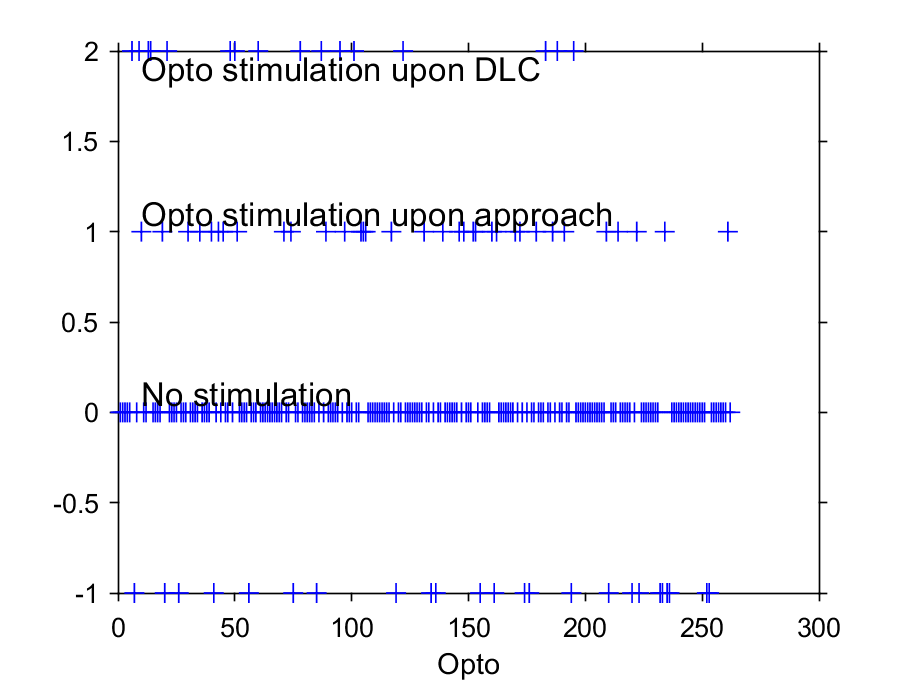


figure;

plot(OptoStim, 'b+')
xlabel('Opto')
text(10, 0.1, 'No stimulation')
text(10, 1.1, 'Opto stimulation upon approach')
text(10, 1.9, 'Opto stimulation upon DLC')


sprintf('Number of DLC stim trials %2.0d', length(find(OptoStim==2)))

ans = 'Number of DLC stim trials 16'

sprintf('Number of Approach stim trials %2.0d', length(find(OptoStim==1)))

ans = 'Number of Approach stim trials 34'

sprintf('Number of No stim trials %2.0d', length(find(OptoStim==0)))

ans = 'Number of No stim trials 188'

sprintf('Ratio of stim vs total %2.2f%%', (length(find(OptoStim==2))+length(find(OptoStim==1)))/(length(find(OptoStim~=-1))))

ans = 'Ratio of stim vs total 0.21%'

sprintf('Number of  discarded trials %2.0d', length(find(OptoStim==-1)))

ans = 'Number of  discarded trials 24'

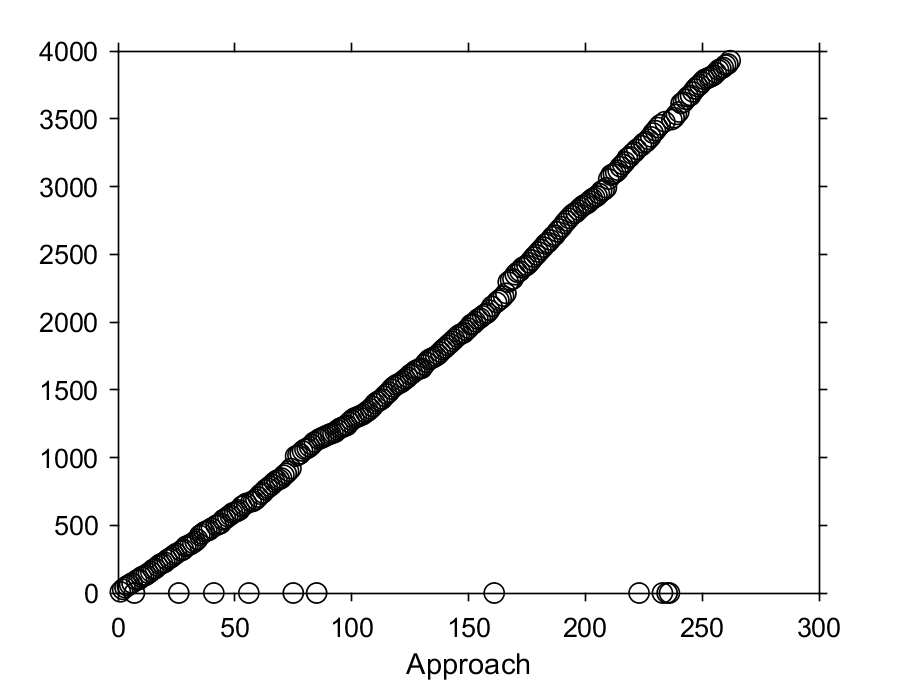



figure; 
plot(ApproachTime, 'ko')
xlabel('Approach')

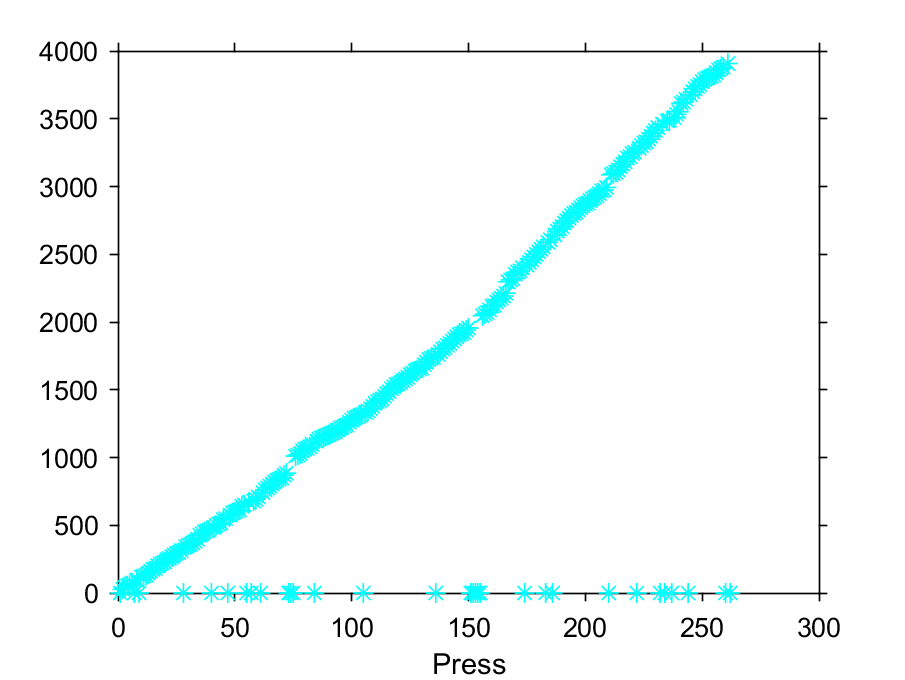


figure; 
plot(PressTime, 'c*')
xlabel('Press')

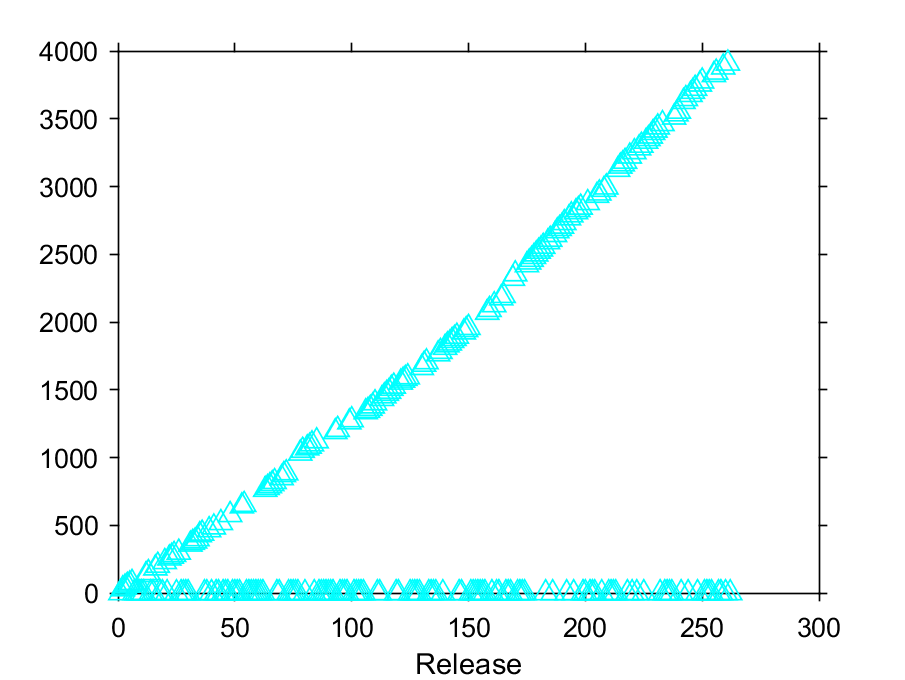


figure
plot(ReleaseTime, 'c^')
xlabel('Release')

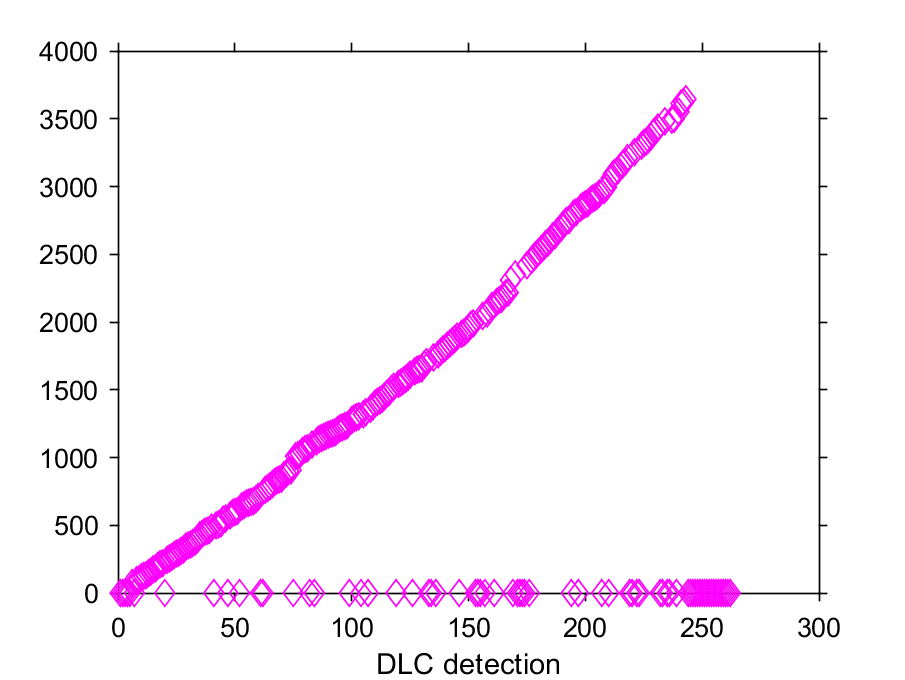


figure; 
plot(DLCTime, 'md')
xlabel('DLC detection')

#############################
########## Please wait #########
#############################


ans = 'check seqson 100 of 231'

ans = 'check seqson 200 of 231'

Elapsed time is 17.288144 seconds.


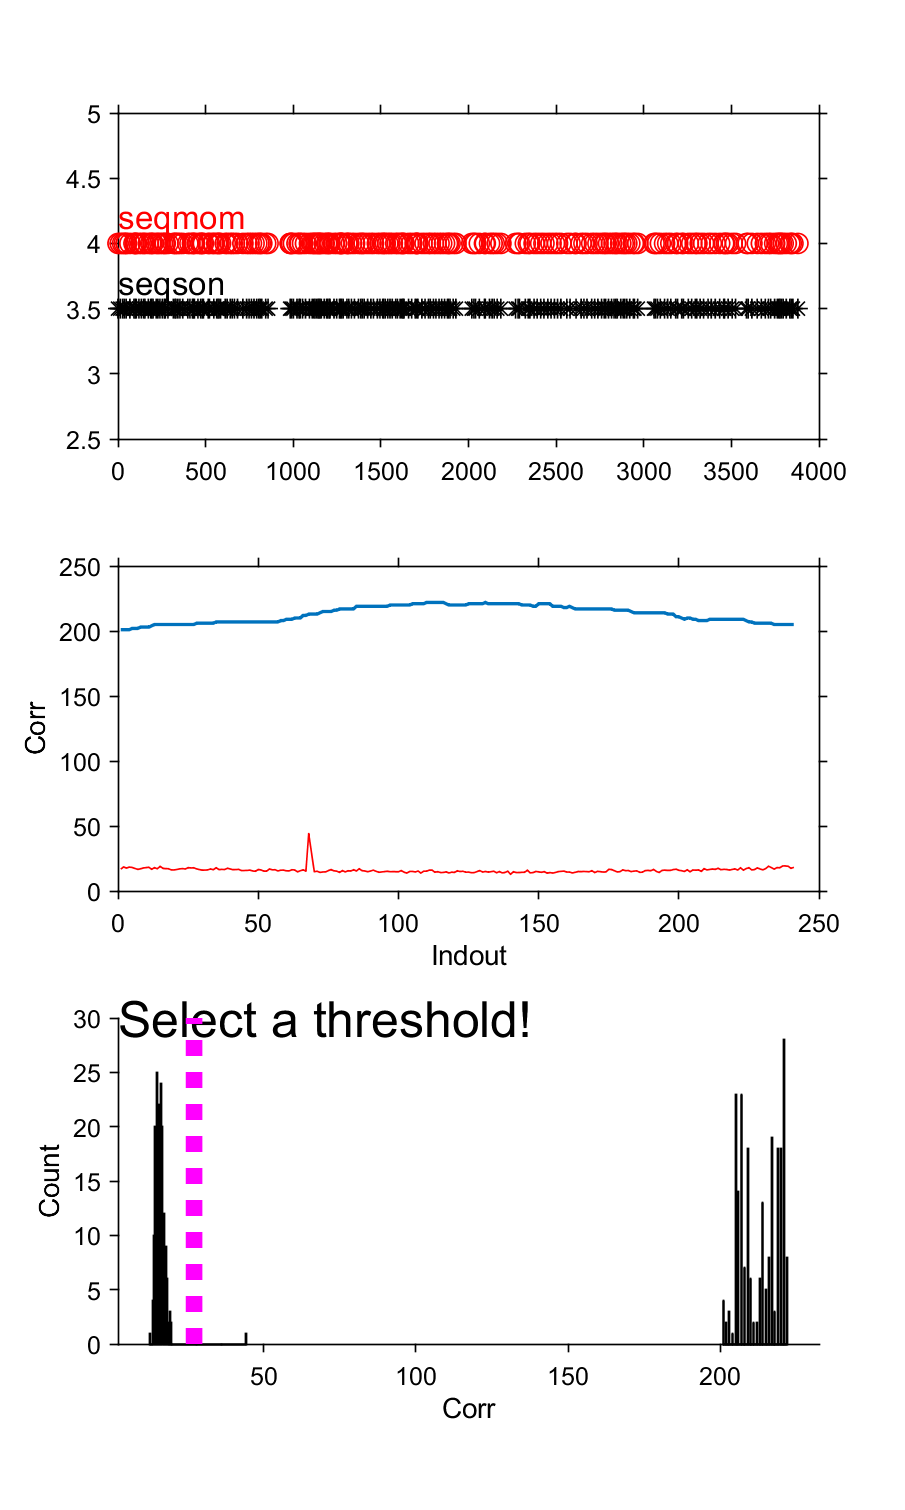


% Make a useful table. 

TrialsBpod       =     [1:SessionData.nTrials]';
tApproach       =     ApproachTime';
tPress          =     PressTime';
tRelease        =     ReleaseTime';
tDLC            =     DLCTime';
tTrigger        =     TriggerTime';


DLCtoPressLatency = tPress - tDLC;

FrameIdxAtDLCTime =     FrameIdxDCLTime';
FrameTimeAtDLCTime =    tFrameDCLTime';


RatName          =      repmat(b.Metadata.SubjectName, SessionData.nTrials, 1);
Date             =      repmat(SessionData.Info.SessionDate, SessionData.nTrials, 1);
ExpTime          =      repmat(SessionData.Info.SessionStartTime_UTC, SessionData.nTrials, 1);
MEDProtocolName     =      repmat(b.Metadata.ProtocolName, SessionData.nTrials, 1);
MEDFileName         =  repmat(MEDFile.name, SessionData.nTrials, 1);
BpodFileName     =      repmat('Claire_MedOptoRecMix_20220124_143611.mat', SessionData.nTrials, 1);

% map each trial that contains a press time to b

tPress2        =    tPress(tPress~=0);
IndBpodInMed   =    findseqmatchrev(b.PressTime, tPress2, 0 , 1);

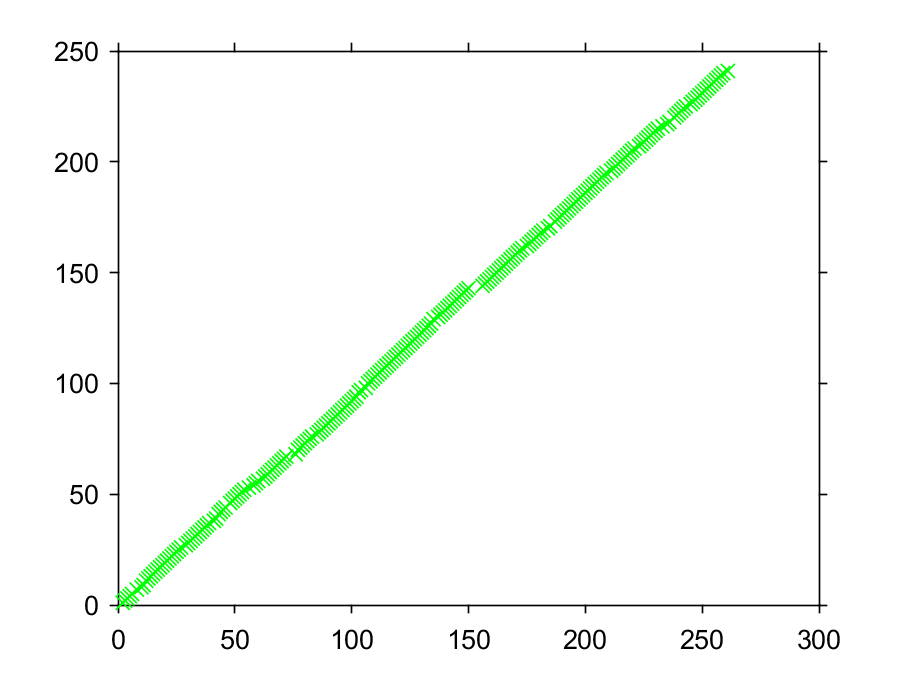


IndTrials     =     zeros(size(tPress));
IndTrials(tPress~=0)   =   IndBpodInMed;
IndTrials(tPress==0)   =   NaN;     

IndBpod2MED = IndTrials;

FPs = NaN*ones(length(TrialsBpod), 1);
FPs(find(~isnan(IndBpod2MED))) = b.FPs(IndBpod2MED(~isnan(IndBpod2MED)));

% fullfill some missing release time
for j = 1:length(tRelease)
    if tPress(j)~=0 && tRelease(j) == 0
        indMED = IndBpod2MED(j);
        tRelease(j) = b.ReleaseTime(indMED) - b.PressTime(indMED) + tPress(j);
    end;
end;

Performance = cell(length(TrialsBpod), 1);

for i =1:length(IndBpod2MED)
    if ~isnan(IndBpod2MED(i))
        if ismember(IndBpod2MED(i), b.Correct)
            Performance{i} = 'Correct';
        elseif ismember(IndBpod2MED(i), b.Premature)
            Performance{i} = 'Premature';
        elseif ismember(IndBpod2MED(i), b.Late)
            Performance{i} = 'Late';
        elseif  ismember(IndBpod2MED(i), b.Dark)
            Performance{i} = 'Late';
        else
            Performance{i} = 'Unknown';
        end;
    end;
end;

figure; plot(IndTrials, 'gx')

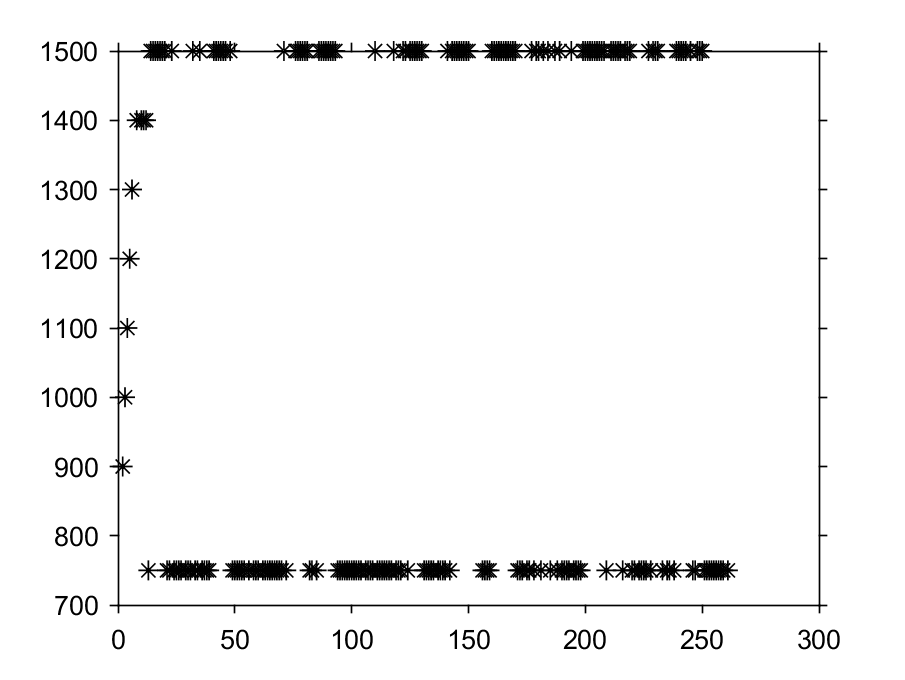

figure; plot(FPs, 'k*')




btable        =     table(RatName, Date, TrialsBpod, IndBpod2MED, FPs, Performance, tApproach, tPress, tTrigger, tRelease, tDLC, OptoStimTypes, FrameIdxAtDLCTime, FrameTimeAtDLCTime, MEDProtocolName, MEDFileName, BpodFileName, ExpTime);
aGoodName       =     ['BpodMEDTable' '_' b.Metadata.SubjectName, '_' b.Metadata.Date '.csv']

aGoodName = 'BpodMEDTable_Claire_20220117.csv'


writetable(btable, aGoodName)

Unable to open file 'E:\DLSOpt\Data\ANMs\Claire\Sessions\20220117\BpodMEDTable_Claire_20220117.csv' for writing:

Permission denied

% Extract all triggered frames. Mark them with Bpod's trial number

% for each DLC-triggered frame, make a short sequence from tDLC to
% tDLC+2 s, 100 frames in total

% MakeAVIDLCLive(aGoodName);
% MakeAVIApproach(aGoodName);


### Now that table has been generated, let's look at the results

% load the table
TblName = aGoodName;
btable = readtable(TblName);

display(btable)

hf_results = figure(124); 
clf
set(hf_results, 'units', 'centimeters', 'position',[2 2 12 7], 'paperpositionmode', 'auto','renderer','Painters' , 'Visible','on')

% plot a few things:
% 1. Approach to press time for all trials
ha1 = axes('units', 'centimeters', 'Position',[2 2 3 4], 'xlim', [0 4], 'xtick', [1 3], 'xticklabel', {'NoStim', 'Stim'},'ylim', [0 4], 'nextplot', 'add');

App2Press = cell(1, 2);% 1, nostim, 2, stim
for   i = 1:length(btable.TrialsBpod)
    if btable.tApproach(i)>0 && btable.tPress(i)>0 && btable.tPress(i)-btable.tApproach(i)>0
        istim = btable.OptoStimTypes{i};
        switch istim
            case 'NoStim'
                App2Press{1} = [App2Press{1} btable.tPress(i)-btable.tApproach(i)];
            case 'Stim_Approach'
                App2Press{2} = [App2Press{2} btable.tPress(i)-btable.tApproach(i)];
        end
    end;
end;

plot(ha1, rand(1, length(App2Press{1}))-0.5+1, App2Press{1}, 'o', 'markerfacecolor', [0.8 0.8 0.8], 'markeredgecolor', 'w', 'markersize', 4)
line(ha1, [0.75 1.25], median(App2Press{1})*[1 1], 'color', 'k', 'linewidth', 2)

plot(ha1, rand(1, length(App2Press{2}))-0.5+3, App2Press{2}, 'o', 'markerfacecolor', [0 184 255]/255, 'markeredgecolor', 'w', 'markersize', 4)
line(ha1, [0.75 1.25]+2, median(App2Press{2})*[1 1], 'color', 0.5*[0 184 255]/255, 'linewidth', 2)

sprintf('approach to press is %2.2f s (nostim) and %2.2f s (stim), difference is %2.2f s', median(App2Press{1}), median(App2Press{2}), median(App2Press{2}) - median(App2Press{1}))

xlabel('')
ylabel('Approach to press (sec)')
title(Date(1, :))

% 2. DLC to press time for all trials
ha2 = axes('units', 'centimeters', 'Position',[7 2 3 4], 'xlim', [0 4], 'xtick', [1 3], 'xticklabel', {'NoStim', 'Stim'},'ylim', [0 4],'nextplot', 'add');

DLC2Press = cell(1, 2);% 1, nostim, 2, stim
for   i = 1:length(btable.TrialsBpod)
    if btable.tDLC(i)>0 && btable.tPress(i)>0 && btable.tPress(i)-btable.tDLC(i)>0

        if btable.tPress(i)-btable.tDLC(i)>5
            sprintf('%2.0d', i)
        end;

        istim = btable.OptoStimTypes{i};
        switch istim
            case 'NoStim'
                DLC2Press{1} = [DLC2Press{1} btable.tPress(i)-btable.tDLC(i)];
            case 'Stim_DLC'
                DLC2Press{2} = [DLC2Press{2} btable.tPress(i)-btable.tDLC(i)];
        end
    end;
end;

plot(ha2, rand(1, length(DLC2Press{1}))-0.5+1, DLC2Press{1}, 'o', 'markerfacecolor', [0.8 0.8 0.8], 'markeredgecolor', 'w', 'markersize', 4)
line(ha2, [0.75 1.25], median(DLC2Press{1})*[1 1], 'color', 'k', 'linewidth', 2)

plot(ha2, rand(1, length(DLC2Press{2}))-0.5+3, DLC2Press{2}, 'o', 'markerfacecolor', [0 184 255]/255, 'markeredgecolor', 'w', 'markersize', 4)
line(ha2, [0.75 1.25]+2, median(DLC2Press{2})*[1 1], 'color', 0.5*[0 184 255]/255, 'linewidth', 2)

sprintf('DLC to press is %2.2f s (nostim) and %2.2f s (stim), difference is %2.2f s', median(DLC2Press{1}), median(DLC2Press{2}), median(DLC2Press{2}) - median(DLC2Press{1}))

xlabel('')
ylabel('DLC to press (sec)')


tosavename=  ['LatencyComparison_ApproachVsDLC'];

export_fig('hf_results', '-eps', '-png'); 